# Modifying a Local Function

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data and plots the distribution of total medal counts

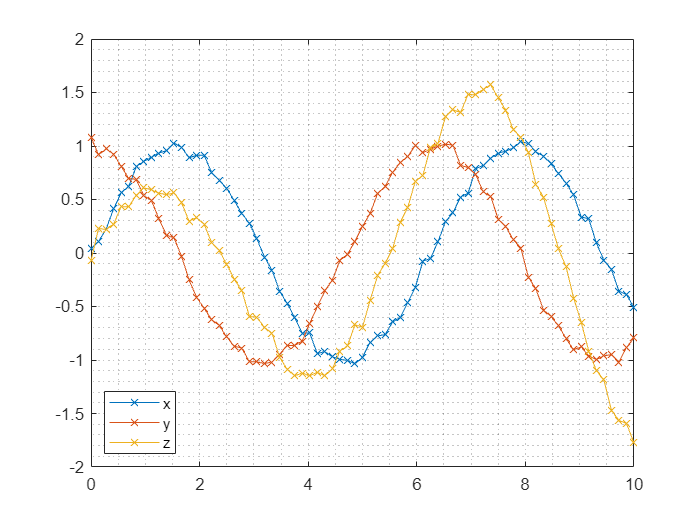

rng(123)
n = 73;
t = linspace(0, 10, n);
x = sin(t) + 0.05*randn(1, n);
y = cos(t) + 0.05*randn(1, n);
z = 0.4*sqrt(t).*(sin(t) + cos(t)) + 0.05*randn(1, n);

plot(t, x, "x-", t, y, "x-", t, z, "x-")
grid minor
legend(["x", "y", "z"], "Location", "southwest")

## Task 1

The script shown contains a function `findcrossing` that takes two vectors (`x` and `y`) as input, representing data points from a function y(x). The output from `findcrossing` is a vector of estimated x values for which y(x) = 0.

Rather than find where y(x) = 0, you might want to find where y(x) crosses some other value. Note that y(x) = y0 is equivalent to y(x) - y0 = 0. This means you can use the same approach as before by simply changing the `y` values (by subtracting y0).

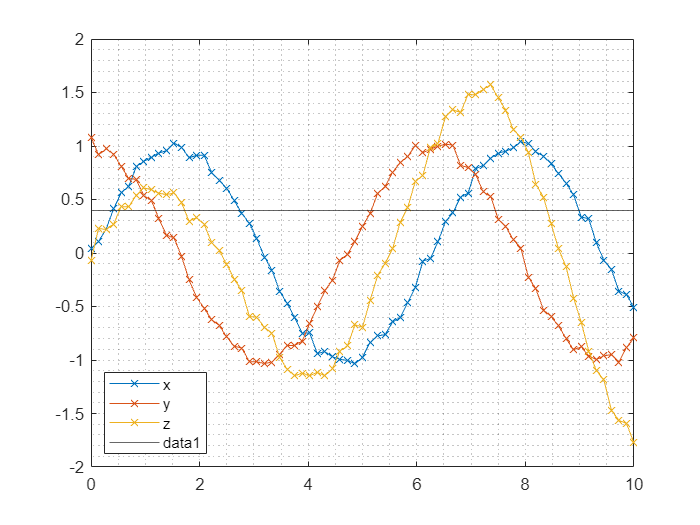

y0 = 0.4;
yline(y0)


tzerox = findcrossing(t, x, y0)

tzerox =     0.4060    2.7436    6.6888    8.9848


tzeroy = findcrossing(t, y, y0)

tzeroy =     1.1860    5.1627    7.4448


## Task 2

Although the new third input to `findcrossing` was assumed to be a scalar value, there is nothing to prevent it being another vector (the same size as `y`).

Passing a vector `z` will find the values of t such that y(t) - z(t) = 0 or y(t) = z(t). That is, you can call `findcrossing` with three vector inputs to find where two graphs intersect.

tcross = findcrossing(t, x, y)

tcross =     0.7472    3.9527    7.0589


function xcross = findcrossing(x, y, z)
    y = y - z;
    % Indices where current value and next value have opposite sign
    idx = find(y(1:end-1).*y(2:end) <= 0);
    % Linear interpolation between indices and next point
    xcross = (x(idx).*y(idx+1) - x(idx+1).*y(idx)) ./ (y(idx+1) - y(idx));
end